clc,clear;
%iosr.dsp.ltas command fromChristopher Hummersone (2023). Long term average spectrum (https://github.com/IoSR-Surrey/MatlabToolbox), GitHub. Retrieved February 22, 2023.

%Country 80s

[P1,fs]=audioread("Coward Of The Country.wav");
[P2,fs]=audioread("9 to 5.wav");
[P3,fs]=audioread("I Love a Rainy Night.wav");
[P4,fs]=audioread("Lookin For Love.wav");
[P5,fs]=audioread("I Believe In You.wav");
[P6,fs]=audioread("On The Road Again.wav");
[P7,fs]=audioread("Seven Year Ache.wav");
[P8,fs]=audioread("I Don't Need You.wav");
[P9,fs]=audioread("Love In The First Degree.wav");
[P10,fs]=audioread("Blessed Are The Believers.wav");
[P11,fs]=audioread("Always On My Mind.wav");
[P12,fs]=audioread("Shame on the Moon.wav");
[P13,fs]=audioread("Fourteen Carat Mind.wav");
[P14,fs]=audioread("Bobbie Sue.wav");
[P15,fs]=audioread("Islands In The Stream.wav");
[P16,fs]=audioread("You Can Not Run From Love.wav");
[P17,fs]=audioread("Lady Down On Love.wav");
[P18,fs]=audioread("Never Be You.wav");
[P19,fs]=audioread("Deep River Woman.wav");
[P20,fs]=audioread("Forever And Ever Amen.wav");



figure
[S1,F]=iosr.dsp.ltas(P1,fs,'noct',6,'graph',true,'units','dB');
hold on;
[S2,F]=iosr.dsp.ltas(P2,fs,'noct',6,'graph',false,'units','dB');
[S3,F]=iosr.dsp.ltas(P3,fs,'noct',6,'graph',false,'units','dB');
[S4,F]=iosr.dsp.ltas(P4,fs,'noct',6,'graph',false,'units','dB');
[S5,F]=iosr.dsp.ltas(P5,fs,'noct',6,'graph',false,'units','dB');
[S6,F]=iosr.dsp.ltas(P6,fs,'noct',6,'graph',false,'units','dB');
[S7,F]=iosr.dsp.ltas(P7,fs,'noct',6,'graph',false,'units','dB');
[S8,F]=iosr.dsp.ltas(P8,fs,'noct',6,'graph',false,'units','dB');
[S9,F]=iosr.dsp.ltas(P9,fs,'noct',6,'graph',false,'units','dB');
[S10,F]=iosr.dsp.ltas(P10,fs,'noct',6,'graph',false,'units','dB');
[S11,F]=iosr.dsp.ltas(P11,fs,'noct',6,'graph',false,'units','dB');
[S12,F]=iosr.dsp.ltas(P12,fs,'noct',6,'graph',false,'units','dB');
[S13,F]=iosr.dsp.ltas(P13,fs,'noct',6,'graph',false,'units','dB');
[S14,F]=iosr.dsp.ltas(P14,fs,'noct',6,'graph',false,'units','dB');
[S15,F]=iosr.dsp.ltas(P15,fs,'noct',6,'graph',false,'units','dB');
[S16,F]=iosr.dsp.ltas(P16,fs,'noct',6,'graph',false,'units','dB');
[S17,F]=iosr.dsp.ltas(P17,fs,'noct',6,'graph',false,'units','dB');
[S18,F]=iosr.dsp.ltas(P18,fs,'noct',6,'graph',false,'units','dB');
[S19,F]=iosr.dsp.ltas(P19,fs,'noct',6,'graph',false,'units','dB');
[S20,F]=iosr.dsp.ltas(P20,fs,'noct',6,'graph',false,'units','dB');



S=[S1(:), S2(:),S3(:),S4(:),S5(:),S6(:),S7(:),S8(:),S9(:),S10(:),S11(:),S12(:),S13(:),S14(:),S15(:),S16(:),S17(:),S18(:),S19(:),S20(:)];
S=S.';
MS=mean(S);




%plot(F,MS,LineWidth=2,Color='r');

%Source for plot function
% Christopher Hummersone (2023). Long term average spectrum (https://github.com/IoSR-Surrey/MatlabToolbox), GitHub. Retrieved February 22, 2023.


hold on;
MS=MS.'

MS =   -63.6990
  -63.4391
  -59.5152
  -48.7160
  -40.3226
  -37.0588
  -37.1579
  -37.7895
  -37.4553
  -37.6333


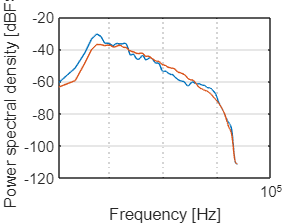

NFFT = 4096;
win = NFFT;
hop=NFFT/2;

dims = size(MS);
dim = find(dims>1,1,'first');
if mod(NFFT,2)==0
        Nout = (NFFT/2)+1;
    else
        Nout = (NFFT+1)/2;
    end
order = mod(dim-1:dim+length(dims)-2,length(dims))+1;
dims_shift = dims(order);
x = rearrange(MS,order,[dims_shift(1) prod(dims_shift(2:end))]);
dims_out_shift = dims_shift;
dims_out_shift(1) = Nout;
units = @(x) 10*log10(x);
max0scale = @(s) s-max(s(:));
labelY = 'Power spectral density [dBFS]';
yscale = 'linear';



semilogx(F,rearrange(MS,order,[dims_out_shift(1) prod(dims_out_shift(2:end))]));
xlabel('Frequency [Hz]');
ylabel(labelY);
set(gca,'yscale',yscale);
grid on

if prod(dims_out_shift(2:end)) > 1
   legend(num2str((1:prod(dims_out_shift(2:end)))'));
end




%Country 2000s


[P21,fz]=audioread("I Hope You Dance.wav");
[P22,fz]=audioread("The Way You Love Me.wav");
[P23,fz]=audioread("Austin.wav");
[P24,fz]=audioread("Where the Stars and Stripes and the Eagle Fly.wav");
[P25,fz]=audioread("The Good Stuff.wav");
[P26,fz]=audioread("My List.wav");
[P27,fz]=audioread("19 Somethin.wav");
[P28,fz]=audioread("There Goes My Life.wav");
[P29,fz]=audioread("Live Like You Were Dying.wav");
[P30,fz]=audioread("Redneck Woman.wav");
[P31,fz]=audioread("As Good as I Once Was.wav");
[P32,fz]=audioread("Jesus Take the Wheel.wav");
[P33,fz]=audioread("Mississippi Girl.wav");
[P34,fz]=audioread("Summertime.wav");
[P35,fz]=audioread("She is Everything.wav");
[P36,fz]=audioread("Our Song.wav");
[P37,fz]=audioread("Watching You.wav");
[P38,fz]=audioread("Letter To Me.wav");
[P39,fz]=audioread("You are Gonna Miss This.wav");
[P40,fz]=audioread("Need You Now.wav");

figure
[PP1,FZ]=iosr.dsp.ltas(P21,fz,'noct',6,'graph',true,'units','dB');
hold on;
[PP2,FZ]=iosr.dsp.ltas(P22,fz,'noct',6,'graph',false,'units','dB');
[PP3,FZ]=iosr.dsp.ltas(P23,fz,'noct',6,'graph',false,'units','dB');
[PP4,FZ]=iosr.dsp.ltas(P24,fz,'noct',6,'graph',false,'units','dB');
[PP5,FZ]=iosr.dsp.ltas(P25,fz,'noct',6,'graph',false,'units','dB');
[PP6,FZ]=iosr.dsp.ltas(P26,fz,'noct',6,'graph',false,'units','dB');
[PP7,FZ]=iosr.dsp.ltas(P27,fz,'noct',6,'graph',false,'units','dB');
[PP8,FZ]=iosr.dsp.ltas(P28,fz,'noct',6,'graph',false,'units','dB');
[PP9,FZ]=iosr.dsp.ltas(P29,fz,'noct',6,'graph',false,'units','dB');
[PP10,FZ]=iosr.dsp.ltas(P30,fz,'noct',6,'graph',false,'units','dB');
[PP11,FZ]=iosr.dsp.ltas(P31,fz,'noct',6,'graph',false,'units','dB');
[PP12,FZ]=iosr.dsp.ltas(P32,fz,'noct',6,'graph',false,'units','dB');
[PP13,FZ]=iosr.dsp.ltas(P33,fz,'noct',6,'graph',false,'units','dB');
[PP14,FZ]=iosr.dsp.ltas(P34,fz,'noct',6,'graph',false,'units','dB');
[PP15,FZ]=iosr.dsp.ltas(P35,fz,'noct',6,'graph',false,'units','dB');
[PP16,FZ]=iosr.dsp.ltas(P36,fz,'noct',6,'graph',false,'units','dB');
[PP17,FZ]=iosr.dsp.ltas(P37,fz,'noct',6,'graph',false,'units','dB');
[PP18,FZ]=iosr.dsp.ltas(P38,fz,'noct',6,'graph',false,'units','dB');
[PP19,FZ]=iosr.dsp.ltas(P39,fz,'noct',6,'graph',false,'units','dB');
[PP20,FZ]=iosr.dsp.ltas(P40,fz,'noct',6,'graph',false,'units','dB');



P2000=[PP1(:), PP2(:),PP3(:),PP4(:),PP5(:),PP6(:),PP7(:),PP8(:),PP9(:),PP10(:),PP11(:),PP12(:),PP13(:),PP14(:),PP15(:),PP16(:),PP17(:),PP18(:),PP19(:),PP20(:)];
P2000=P2000.';
MP2000=mean(P2000);




plot(FZ,MP2000,LineWidth=2,Color='r');

%Source for plot function
% Christopher Hummersone (2023). Long term average spectrum (https://github.com/IoSR-Surrey/MatlabToolbox), GitHub. Retrieved February 22, 2023.

hold on;
MP2000=MP2000.'

MP2000 =   -59.2662
  -56.2433
  -48.2772
  -40.7635
  -36.6129
  -34.7292
  -34.0830
  -34.1643
  -34.6248
  -34.4216


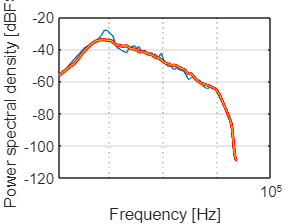

NFFT = 4096;
win = NFFT;
hop=NFFT/2;

dims = size(MP2000);
dim = find(dims>1,1,'first');
if mod(NFFT,2)==0
        Nout = (NFFT/2)+1;
    else
        Nout = (NFFT+1)/2;
    end
order = mod(dim-1:dim+length(dims)-2,length(dims))+1;
dims_shift = dims(order);
x = rearrange(MP2000,order,[dims_shift(1) prod(dims_shift(2:end))]);
dims_out_shift = dims_shift;
dims_out_shift(1) = Nout;
units = @(x) 10*log10(x);
max0scale = @(s) s-max(s(:));
labelY = 'Power spectral density [dBFS]';
yscale = 'linear';



semilogx(FZ,rearrange(MP2000,order,[dims_out_shift(1) prod(dims_out_shift(2:end))]));
xlabel('Frequency [Hz]');
ylabel(labelY);
set(gca,'yscale',yscale);
grid on

if prod(dims_out_shift(2:end)) > 1
   legend(num2str((1:prod(dims_out_shift(2:end)))'));
end

%Country 2020s


[P41,fq]=audioread("More Than My Hometown.wav");
[P42,fq]=audioread("One Margarita.wav");
[P43,fq]=audioread("One Of Them Girls.wav");
[P44,fq]=audioread("Hard to Forget.wav");
[P45,fq]=audioread("Here and Now.wav");
[P46,fq]=audioread("Beer Can Not Fix.wav");
[P47,fq]=audioread("God Whispered Your Name.wav");
[P48,fq]=audioread("Hole in the Bottle.wav");
[P49,fq]=audioread("Forever After All.wav");
[P50,fq]=audioread("Starting Over.wav");
[P51,fq]=audioread("Things a Man Oughta Know.wav");
[P52,fq]=audioread("Better Together.wav");
[P53,fq]=audioread("The Good Ones.wav");
[P54,fq]=audioread("Buy Dirt.wav");
[P55,fq]=audioread("Fancy Like.wav");
[P56,fq]=audioread("You Time.wav");
[P57,fq]=audioread("I Was on a Boat That Day.wav");
[P58,fq]=audioread("My Boy.wav");
[P59,fq]=audioread("Settling Down.wav");
[P60,fq]=audioread("Half of My Hometown.wav");

figure
[Q1,FQ]=iosr.dsp.ltas(P41,fq,'noct',6,'graph',true,'units','dB');
hold on;
[Q2,FQ]=iosr.dsp.ltas(P42,fq,'noct',6,'graph',false,'units','dB');
[Q3,FQ]=iosr.dsp.ltas(P43,fq,'noct',6,'graph',false,'units','dB');
[Q4,FQ]=iosr.dsp.ltas(P44,fq,'noct',6,'graph',false,'units','dB');
[Q5,FQ]=iosr.dsp.ltas(P45,fq,'noct',6,'graph',false,'units','dB');
[Q6,FQ]=iosr.dsp.ltas(P46,fq,'noct',6,'graph',false,'units','dB');
[Q7,FQ]=iosr.dsp.ltas(P47,fq,'noct',6,'graph',false,'units','dB');
[Q8,FQ]=iosr.dsp.ltas(P48,fq,'noct',6,'graph',false,'units','dB');
[Q9,FQ]=iosr.dsp.ltas(P49,fq,'noct',6,'graph',false,'units','dB');
[Q10,FQ]=iosr.dsp.ltas(P50,fq,'noct',6,'graph',false,'units','dB');
[Q11,FQ]=iosr.dsp.ltas(P51,fq,'noct',6,'graph',false,'units','dB');
[Q12,FQ]=iosr.dsp.ltas(P52,fq,'noct',6,'graph',false,'units','dB');
[Q13,FQ]=iosr.dsp.ltas(P53,fq,'noct',6,'graph',false,'units','dB');
[Q14,FQ]=iosr.dsp.ltas(P54,fq,'noct',6,'graph',false,'units','dB');
[Q15,FQ]=iosr.dsp.ltas(P55,fq,'noct',6,'graph',false,'units','dB');
[Q16,FQ]=iosr.dsp.ltas(P56,fq,'noct',6,'graph',false,'units','dB');
[Q17,FQ]=iosr.dsp.ltas(P57,fq,'noct',6,'graph',false,'units','dB');
[Q18,FQ]=iosr.dsp.ltas(P58,fq,'noct',6,'graph',false,'units','dB');
[Q19,FQ]=iosr.dsp.ltas(P59,fq,'noct',6,'graph',false,'units','dB');
[Q20,FQ]=iosr.dsp.ltas(P50,fq,'noct',6,'graph',false,'units','dB');

P2020=[Q1(:), Q2(:),Q3(:),Q4(:),Q5(:),Q6(:),Q7(:),Q8(:),Q9(:),Q10(:),Q11(:),Q12(:),Q13(:),Q14(:),Q15(:),Q16(:),Q17(:),Q18(:),Q19(:),Q20(:)];
P2020=P2020.';
MP2020=mean(P2020);




plot(FQ,MP2020,LineWidth=2,Color='r');

%Source for plot function
% Christopher Hummersone (2023). Long term average spectrum (https://github.com/IoSR-Surrey/MatlabToolbox), GitHub. Retrieved February 22, 2023.

hold on;
MP2020=MP2020.'

MP2020 =   -56.3399
  -54.1987
  -46.8978
  -38.2990
  -32.5352
  -30.9111
  -31.2696
  -32.1257
  -33.2489
  -33.0481


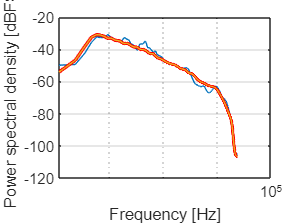

NFFT = 4096;
win = NFFT;
hop=NFFT/2;

dims = size(MP2020);
dim = find(dims>1,1,'first');
if mod(NFFT,2)==0
        Nout = (NFFT/2)+1;
    else
        Nout = (NFFT+1)/2;
    end
order = mod(dim-1:dim+length(dims)-2,length(dims))+1;
dims_shift = dims(order);
x = rearrange(MP2020,order,[dims_shift(1) prod(dims_shift(2:end))]);
dims_out_shift = dims_shift;
dims_out_shift(1) = Nout;
units = @(x) 10*log10(x);
max0scale = @(s) s-max(s(:));
labelY = 'Power spectral density [dBFS]';
yscale = 'linear';



semilogx(FQ,rearrange(MP2020,order,[dims_out_shift(1) prod(dims_out_shift(2:end))]));
xlabel('Frequency [Hz]');
ylabel(labelY);
set(gca,'yscale',yscale);
grid on

if prod(dims_out_shift(2:end)) > 1
   legend(num2str((1:prod(dims_out_shift(2:end)))'));
end



figure()
%legend('Pop 2020s','Pop 2000s', 'Pop 80s')
MP2020=MP2020.'

MP2020 =   -56.3399  -54.1987  -46.8978  -38.2990  -32.5352  -30.9111  -31.2696  -32.1257  -33.2489  -33.0481  -33.6963  -34.4617  -34.5592  -34.7538  -35.2336  -36.1394  -36.4702  -36.4231  -36.3129  -36.5030  -36.9534  -37.3702  -37.8362  -38.1901  -38.4295  -38.6566  -38.7354  -38.6352  -38.6830  -39.0514  -39.4919  -39.7905  -39.9932  -40.1640  -40.2553  -40.2324  -40.1755  -40.2141  -40.3827  -40.5934  -40.7611  -40.9104  -41.1267  -41.4371  -41.7763  -42.0576  -42.2486  -42.3790  -42.4957  -42.6201


NFFT = 4096;
win = NFFT;
hop=NFFT/2;

dims = size(MP2020);
dim = find(dims>1,1,'first');
if mod(NFFT,2)==0
        Nout = (NFFT/2)+1;
    else
        Nout = (NFFT+1)/2;
    end
order = mod(dim-1:dim+length(dims)-2,length(dims))+1;
dims_shift = dims(order);
x = rearrange(MP2020,order,[dims_shift(1) prod(dims_shift(2:end))]);
dims_out_shift = dims_shift;
dims_out_shift(1) = Nout;
units = @(x) 10*log10(x);
max0scale = @(s) s-max(s(:));
labelY = 'Power spectral density [dBFS]';
yscale = 'linear';



semilogx(FQ,rearrange(MP2020,order,[dims_out_shift(1) prod(dims_out_shift(2:end))]));
xlabel('Frequency [Hz]');
ylabel(labelY);
set(gca,'yscale',yscale);
grid on

if prod(dims_out_shift(2:end)) > 1
   legend(num2str((1:prod(dims_out_shift(2:end)))'));
end


hold on;
MP2000=MP2000.'

MP2000 =   -59.2662  -56.2433  -48.2772  -40.7635  -36.6129  -34.7292  -34.0830  -34.1643  -34.6248  -34.4216  -35.4807  -36.8412  -37.5026  -37.6631  -37.7934  -38.2581  -38.1910  -38.0103  -37.9772  -38.4013  -39.0262  -39.3671  -39.6435  -39.7991  -39.8587  -40.0303  -40.2022  -40.2375  -40.4286  -40.9315  -41.4124  -41.6084  -41.6179  -41.6052  -41.5841  -41.5098  -41.4403  -41.5142  -41.7642  -42.0494  -42.2192  -42.2776  -42.3416  -42.4891  -42.6897  -42.8618  -42.9574  -42.9932  -43.0245  -43.0983


NFFT = 4096;
win = NFFT;
hop=NFFT/2;

dims = size(MP2000);
dim = find(dims>1,1,'first');
if mod(NFFT,2)==0
        Nout = (NFFT/2)+1;
    else
        Nout = (NFFT+1)/2;
    end
order = mod(dim-1:dim+length(dims)-2,length(dims))+1;
dims_shift = dims(order);
x = rearrange(MP2000,order,[dims_shift(1) prod(dims_shift(2:end))]);
dims_out_shift = dims_shift;
dims_out_shift(1) = Nout;
units = @(x) 10*log10(x);
max0scale = @(s) s-max(s(:));
labelY = 'Power spectral density [dBFS]';
yscale = 'linear';



semilogx(FZ,rearrange(MP2000,order,[dims_out_shift(1) prod(dims_out_shift(2:end))]));
xlabel('Frequency [Hz]');
ylabel(labelY);
set(gca,'yscale',yscale);
grid on

if prod(dims_out_shift(2:end)) > 1
   legend(num2str((1:prod(dims_out_shift(2:end)))'));
end


hold on;
MS=MS.'

MS =   -63.6990  -63.4391  -59.5152  -48.7160  -40.3226  -37.0588  -37.1579  -37.7895  -37.4553  -37.6333  -38.5887  -38.5873  -38.0072  -37.5462  -37.7032  -38.4668  -38.8377  -38.9180  -39.1937  -39.9080  -40.7697  -41.1308  -41.2771  -41.4750  -41.6697  -41.9653  -42.3315  -42.5423  -42.6164  -42.7087  -42.7657  -42.6595  -42.4541  -42.3425  -42.4048  -42.5694  -42.7893  -43.1168  -43.5739  -44.0490  -44.3766  -44.4850  -44.4366  -44.3514  -44.3126  -44.3358  -44.3993  -44.4901  -44.6221  -44.8176


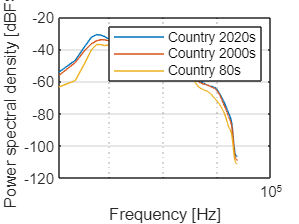

NFFT = 4096;
win = NFFT;
hop=NFFT/2;

dims = size(MS);
dim = find(dims>1,1,'first');
if mod(NFFT,2)==0
        Nout = (NFFT/2)+1;
    else
        Nout = (NFFT+1)/2;
    end
order = mod(dim-1:dim+length(dims)-2,length(dims))+1;
dims_shift = dims(order);
x = rearrange(MS,order,[dims_shift(1) prod(dims_shift(2:end))]);
dims_out_shift = dims_shift;
dims_out_shift(1) = Nout;
units = @(x) 10*log10(x);
max0scale = @(s) s-max(s(:));
labelY = 'Power spectral density [dBFS]';
yscale = 'linear';



semilogx(F,rearrange(MS,order,[dims_out_shift(1) prod(dims_out_shift(2:end))]));
xlabel('Frequency [Hz]');
ylabel(labelY);
set(gca,'yscale',yscale);
grid on

if prod(dims_out_shift(2:end)) > 1
   legend(num2str((1:prod(dims_out_shift(2:end)))'));
end

hold on
legend('Country 2020s', 'Country 2000s', 'Country 80s')
%plot(FQ,MP2020,LineWidth=2,Color='r');
hold off

function y = rearrange(x,order,shape)
%REARRANGE reshape and permute to make target dim column
    y = permute(x,order);
    y = reshape(y,shape);
end

function y = irearrange(x,order,shape)
%IREARRANGE reshape and permute to original size
    y = reshape(x,shape);
    y = ipermute(y,order);
end

%Functions from
% Christopher Hummersone (2023). Long term average spectrum (https://github.com/IoSR-Surrey/MatlabToolbox), GitHub. Retrieved February 22, 2023.

`The MIT License (MIT)`

`Copyright (c) 2016 Institute of Sound Recording`

`Permission is hereby granted, free of charge, to any person obtaining a copy`

`of this software and associated documentation files (the "Software"), to deal`

`in the Software without restriction, including without limitation the rights`

`to use, copy, modify, merge, publish, distribute, sublicense, and/or sell`

`copies of the Software, and to permit persons to whom the Software is`

`furnished to do so, subject to the following conditions:`

`The above copyright notice and this permission notice shall be included in all`

`copies or substantial portions of the Software.`

`THE SOFTWARE IS PROVIDED "AS IS", WITHOUT WARRANTY OF ANY KIND, EXPRESS OR`

`IMPLIED, INCLUDING BUT NOT LIMITED TO THE WARRANTIES OF MERCHANTABILITY,`

`FITNESS FOR A PARTICULAR PURPOSE AND NONINFRINGEMENT. IN NO EVENT SHALL THE`

`AUTHORS OR COPYRIGHT HOLDERS BE LIABLE FOR ANY CLAIM, DAMAGES OR OTHER`

`LIABILITY, WHETHER IN AN ACTION OF CONTRACT, TORT OR OTHERWISE, ARISING FROM,`

`OUT OF OR IN CONNECTION WITH THE SOFTWARE OR THE USE OR OTHER DEALINGS IN THE`

`SOFTWARE.`